# MPO 721 - Homework #1 Spring 2020 (due to 2/26)

## Ivenis Pita 

## 1- $\tau(x,y)=\tau_0.\left\{\hat \imath[-cos(\pi y/L)]+\hat \jmath[cos(\pi x/L).sin(\pi y/L)]\right\}$

#### a) 

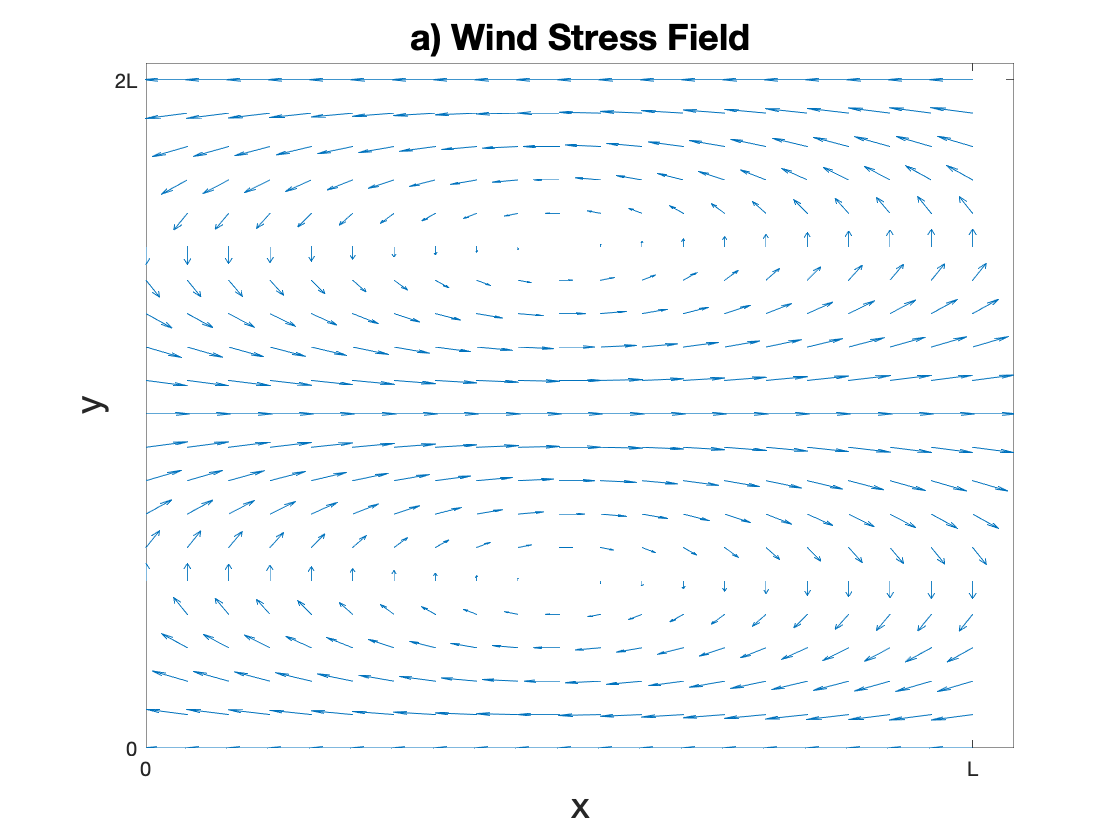

clear variables
close all
clc
L=10;%Definig value of L
res=100;
t0=.1;%[N/m2]
x=[0:L/res:L];%%setting x values
y=[0:2*L/res:2*L];%%setting y values
[X,Y] = meshgrid(x,y);%creating a meshgrid
Tx=t0*(-cos(pi*Y./L));%x component of wind stress
Ty=t0*(cos(pi*X./L).*sin(pi*Y./L));%y component of wind stress

% Ploting the wind field
figure;
%set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
quiver(x(1:res/20:end,1:res/20:end),y(1:res/20:end,1:res/20:end), ...
    Tx(1:res/20:end,1:res/20:end),Ty(1:res/20:end,1:res/20:end),.5);
title('a) Wind Stress Field','Fontsize',18);
xlabel('x','Fontsize',18)
ylabel('y','Fontsize',18)
axis([0 L+.5 0 2*L+.5])
xticks([x(1) x(end)]);
xticklabels({'0','L'});
yticks([y(1) y(end)]);
yticklabels({'0','2L'});

#### b) 2 gyres.

Gyre 1=>     x = [ 0 : L ] ; y = [ 0 : L ]

Gyre 2=>     x = [ 0 : L ] ; y = [ L : 2L ]

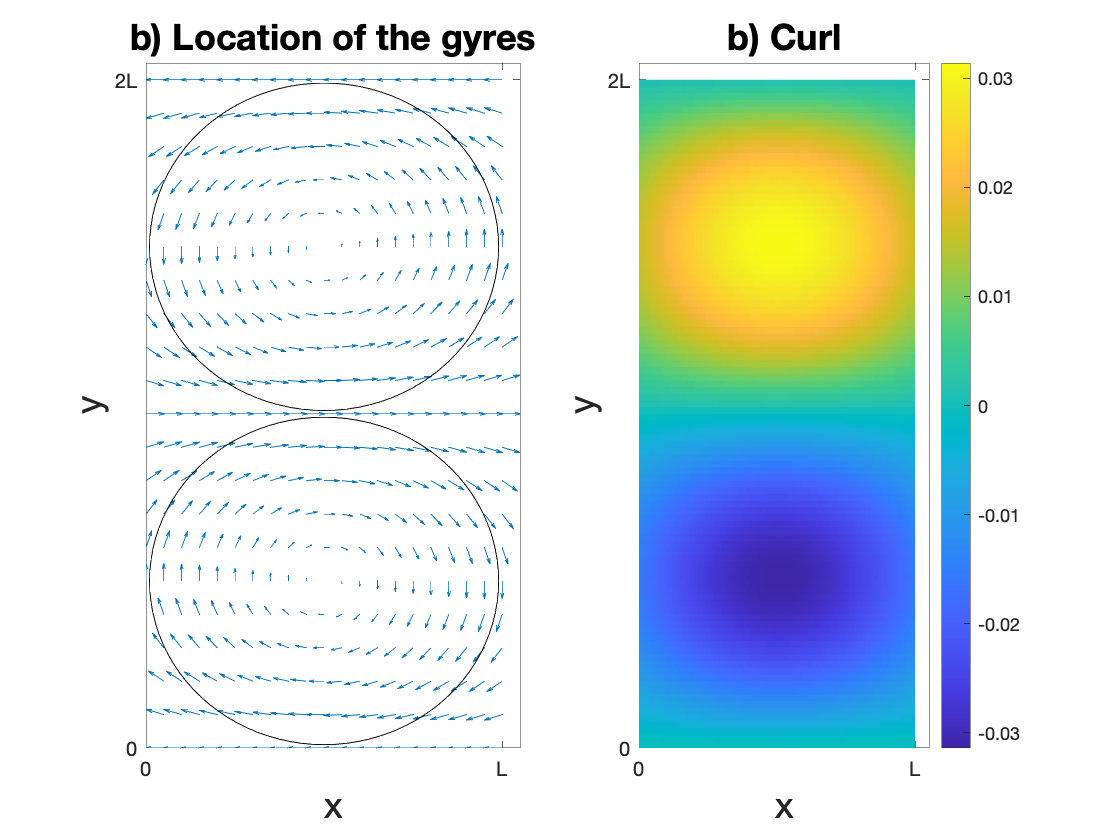

% Ploting the wind field
% wind_curl=curl(x,y,Tx,Ty);
wind_curl=curl(X,Y,Tx,Ty);
figure;
%set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
subplot(121)
quiver(x(1:res/20:end,1:res/20:end),y(1:res/20:end,1:res/20:end),Tx(1:res/20:end,1:res/20:end),...
    Ty(1:res/20:end,1:res/20:end),.5);
title('b) Location of the gyres','Fontsize',18);
xlabel('x','Fontsize',18)
ylabel('y','Fontsize',18)
axis([0 L+.5 0 2*L+.5])
xticks([x(1) x(end)]);
xticklabels({'0','L'});
yticks([y(1) y(end)]);
yticklabels({'0','2L'});

hold on
rectangle('Position',[.1 .1 L-.2 L-.2],'Curvature',1)
hold on
rectangle('Position',[.1 L+.1 L-.2 L-.2],'Curvature',1)

subplot(122)
pcolor(x,y,wind_curl),colorbar,shading flat
title('b) Curl','Fontsize',18);
xlabel('x','Fontsize',18)
ylabel('y','Fontsize',18)
axis([0 L+.5 0 2*L+.5])
xticks([x(1) x(end)]);
xticklabels({'0','L'});
yticks([y(1) y(end)]);
yticklabels({'0','2L'});

#### c) $\tau_0=0.1 Nm^{-2} ; f=10^{-4} s^{-1}; \beta=10^{-11} m^{-1}s^{-1}; L=\pi x 10^3 km $


$$M_y=\frac{\vec \nabla \times \vec \tau_0}{\beta} = \frac{1}{\beta}(\frac{\partial{\tau_0^y}}{\partial{x}} - \frac{\partial{\tau_0^x}}{\partial{y}})$$


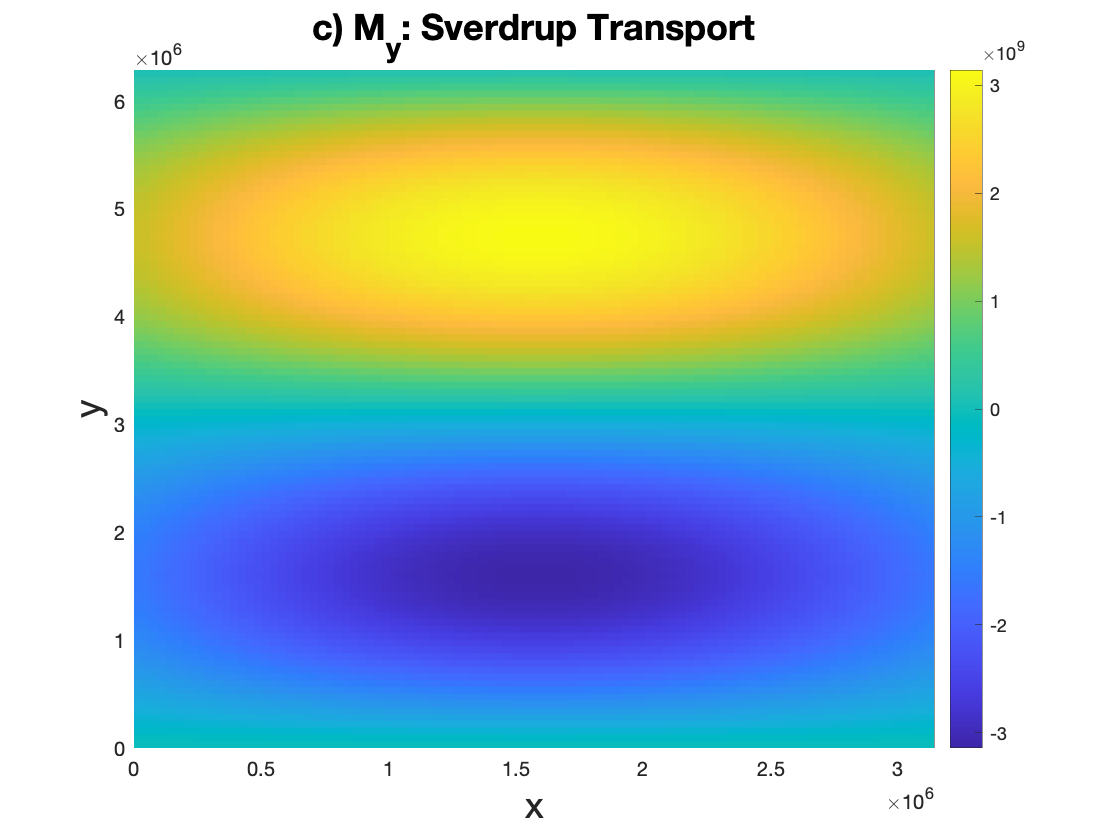

L=pi*1e6;%Definig value of L [m]
t0=.1;%[N/m2]
f=1e-4;%[s^-1]
beta=1e-11;%[1/ms]

x=[0:L/res:L];%%setting x values
y=[0:2*L/res:2*L];%%setting y values
[X,Y] = meshgrid(x,y);%creating a meshgrid
Tx=t0*(-cos(pi*Y./L));%x component of wind stress
Ty=t0*(cos(pi*X./L).*sin(pi*Y./L));%y component of wind stress
My=wind_curl./beta;
%plotting
figure;
%set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
% contour(X(1:10,1:10),Y(1:10,1:10),My)
pcolor(X,Y,My),shading flat
hold on
%quiver(X(1:10,1:10),Y(1:10,1:10),zeros(10),My)
title('c) M_y: Sverdrup Transport','Fontsize',18);
xlabel('x','Fontsize',18)
ylabel('y','Fontsize',18)
colorbar

#### d) $M_e=\frac{\vec \tau_0 \times \hat k}{f} = \frac{1}{f}(\tau_0^y \hat i-\tau_0^x \hat j)$


$$w_e=\frac{1}{\rho} \vec \nabla \cdot \vec M_e=
\frac{1}{f\rho}\ ( \frac{\partial{\tau_0^y}}{\partial{x}} -\frac{\partial{\tau_0^x}}{\partial{y}})$$


where:


$$\tau^y_0=\tau_0cos(\pi x/L)sin(\pi y/L)$$



$$\tau^x_0=-\tau_0cos(\pi y/L)$$



$$w_e=
\frac{1}{f\rho}\ [ \frac{\partial{\tau_0cos(\pi x/L)sin(\pi y/L)}}{\partial{x}} +\frac{\partial{\tau_0cos(\pi y/L)}}{\partial{y}}]$$



$$w_e=
\frac{1}{f\rho}\ [ -\frac{\tau_0 \pi sin(\frac{\pi y}{L}) sin(\frac{\pi x}{L})  } {L}  -\frac{\tau_0 \pi sin(\frac{\pi y}{L})  } {L}]$$



$$w_e=
-\frac{\pi \tau_0 sin(\frac{y\pi}{L})[ sin(\frac{x\pi}{L}) +1]}{f\rho L}$$


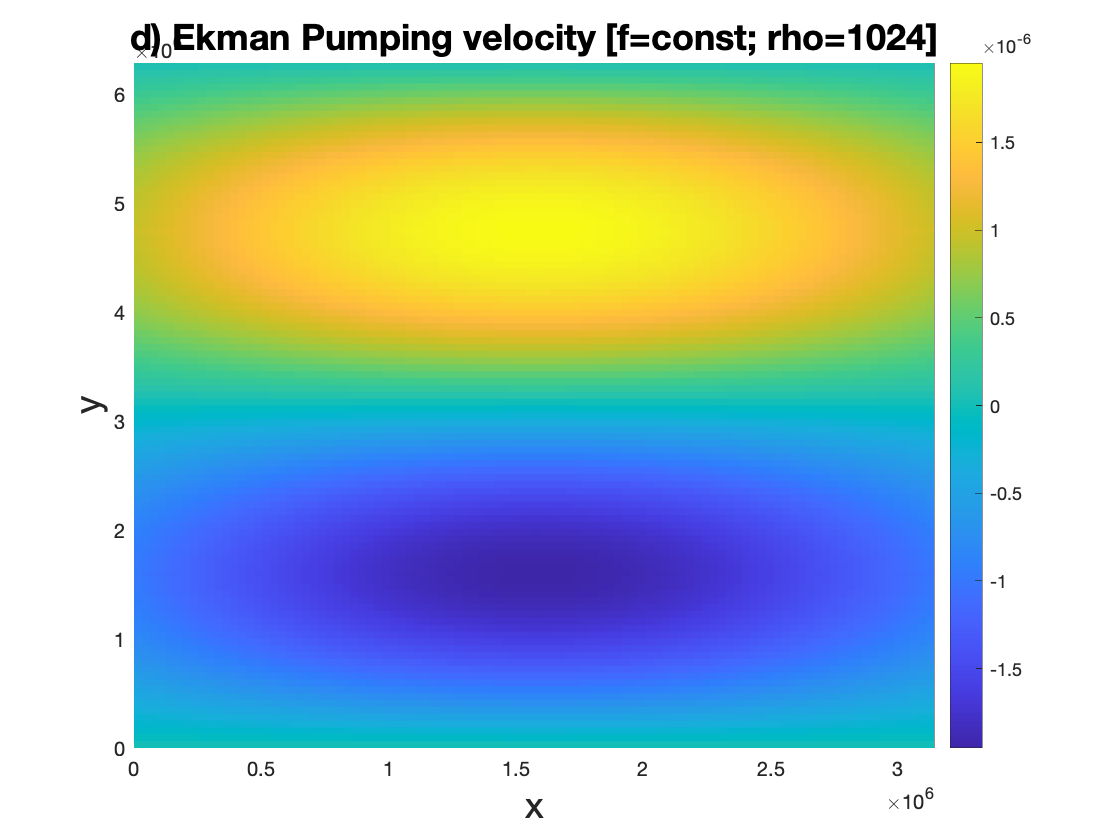

We=  (-pi.*t0.*sin(pi.*Y./L).*(sin(X.*pi./L) +1))   ./(f*L*1024);
%plotting
figure;
%set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
pcolor(X,Y,We),shading flat
%quiver(X(1:10,1:10),Y(1:10,1:10),zeros(10),My)
title('d) Ekman Pumping velocity [f=const; rho=1024]','Fontsize',18);
xlabel('x','Fontsize',18)
ylabel('y','Fontsize',18)
colorbar

#### e) $M_x=-\frac{\partial{\psi}}{\partial{y}}; M_y=\frac{\partial{\psi}}{\partial{x}}
$


$$M_y=\frac{\vec \nabla \times \vec \tau_0}{\beta} = \frac{1}{\beta}(\frac{\partial{\tau_0^y}}{\partial{x}} - \frac{\partial{\tau_0^x}}{\partial{y}})$$



$$\psi (x,y)=\int{M_{y}(x,y)dx} =\int(\frac{1}{\beta}(\frac{\partial{\tau_0^y}}{\partial{x}} - \frac{\partial{\tau_0^x}}{\partial{y}}))dx $$


where:


$$\tau^y_0=\tau_0cos(\pi x/L)sin(\pi y/L)$$



$$\tau^x_0=-\tau_0cos(\pi y/L)$$



$$\psi (x,y)=\frac{1}{\beta}\int(\frac{\partial{\tau_0cos(\pi x/L)sin(\pi y/L)}}{\partial{x}} + \frac{\partial{\tau_0cos(\pi y/L)}}{\partial{y}})dx $$



$$\psi (x,y)=\frac{1}{\beta}\int[ -\frac{\tau_0 \pi sin(\frac {\pi x} {L}) sin(\frac {\pi y} {L})}{L} -\frac{\tau_0 \pi sin(\frac {\pi y} {L}) }{L}] dx$$



$$\psi (x,y)=\frac{1}{\beta}\int[ -\frac{\tau_0 \pi sin(\frac {\pi y} {L}) (sin(\frac {\pi x} {L}+1)}{L} ] dx$$



$$\psi (x,y)=\frac{\tau_0 sin(\frac{\pi y}{L}) [L cos (\frac{\pi x}{L}) -\pi x ]}{\beta L}+c_1$$



$$\psi (L,y)=0$$



$$\frac{\tau_0 sin(\frac{\pi y}{L}) [L cos (\frac{\pi L}{L}) -\pi L ]}{\beta L}+c_1=0$$



$$c_1=-\frac{\tau_0 sin(\frac{\pi y}{L}) [cos (\pi) -\pi]}{\beta}=-\frac{\tau_0 sin(\frac{\pi y}{L}) [-1 -\pi]}{\beta}=\frac{\tau_0 sin(\frac{\pi y}{L}) [1 +\pi]}{\beta}$$



$$\psi (x,y)=\frac{\tau_0 sin(\frac{\pi y}{L}) [L cos (\frac{\pi x}{L}) -\pi x ]}{\beta L}+\frac{\tau_0 sin(\frac{\pi y}{L}) [1 +\pi]}{\beta}$$


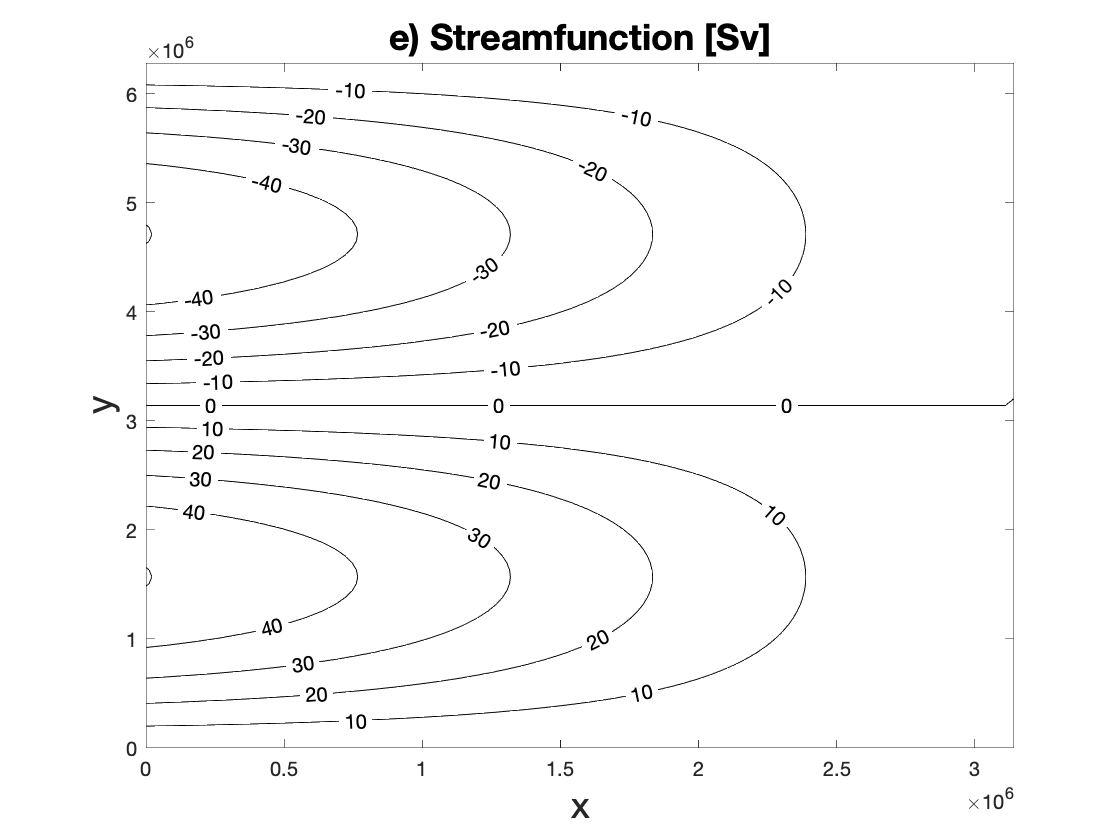

rho=1024;
PSI= (( t0.*sin(pi.*Y./L) .*(L.*cos(pi.*X./L)-pi.*X)   )./(beta*L)) + (  (t0.*sin (pi.*Y/L).*(1+pi)  )./beta);
PSI=PSI./(1e6*rho);%[Sv]
%ploting
figure;
%set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
c=contour(X,Y,PSI,'k','ShowText','on');
title('e) Streamfunction [Sv]','Fontsize',18);
xlabel('x','Fontsize',18)
ylabel('y','Fontsize',18)

#### f) 

Both gyres circulates the same amount of water: 50 Sv

format bank
disp(['Transport = ' num2str(round(max(max(PSI)),2)) ' Sv']);

Transport = 50.21 Sv


## 2-

#### a) $\tau_0^x=-\tau_0 cos(\frac{\pi y}{b})$,


$$\tau_0^y =0$$



$$\psi (x,y)=\int{M_{y}(x,y)dx} =\int(\frac{1}{\beta}(\frac{\partial{\tau_0^y}}{\partial{x}} - \frac{\partial{\tau_0^x}}{\partial{y}}))dx =\int(\frac{\partial{\tau_0 cos(\frac{\pi y}{b})}}{\partial{y}}))dx $$



$$\psi (x,y)=\frac{-1}{\beta}\int _0^L (\frac{\pi \tau_0 sin(\frac{\pi y}{b})}{b})dx$$



$$\psi (y)=-\frac{\tau_0 \pi L }{\beta b} sin(\frac{\pi y}{b})$$


- Stommel


$$\psi (y)=-\frac{\tau_0 \pi L }{\beta b} sin(\frac{\pi y}{b})$$


$V(x,y)=\rho v H=\frac{\psi_I(y)} {Lw} e^{\frac{-x}{Lw}}$, where $\psi_I(y)$ is the Sverdrup transport streamfunction and $Lw=\frac{R}{\beta}=\frac{\mu}{H\beta}$, where $\mu$ is the linear friction coefficient.


$$\rho v H=-\frac{\tau_0 \pi L H \beta }{\beta b \mu} sin(\frac{\pi y}{b}) e^{\frac{-xH\beta}{\mu}}$$


we know that v=2 [m/s] @ x=0 y=b/2, then:


$$2\rho H=-\frac{\tau_0 \pi L H \beta }{\beta b \mu} sin(\frac{\pi b}{2b}) e^{\frac{-0H\beta}{\mu}}=-\frac{\tau_0 \pi L H }{ b \mu} sin(\frac{\pi}{2})$$



$$\mu=-\frac{\tau_0 \pi L H }{ 2 b \rho H} sin(\frac{\pi}{2})=-\frac{\tau_0 \pi L}{ 2 b \rho} =-\frac{0.1 \times \pi \times 5\times10^6}{2\times 1024 \times 3\times10^6}=\frac{-1.57}{6144}=-2.5\times10^{-4}$$



$$Lw_{Stommel}=\frac{\mu} {H\beta}=63.883km$$



$$R=\frac{\mu}{H}=\frac{-2.5 \times 10^{-4}}{200}=1.277 \times 10^{-6}$$


- Munk

        $V(x,y)=\rho v H=\frac{2k}{\sqrt3} \psi_I(y) e^{\frac{-kx}{2}} sin(\frac{kx\sqrt3}{2})$, where $\psi_I(y)$ is the Sverdrup transport streamfunction and $k^{-1}=Lw=\sqrt[3]\frac{A}{\beta}$, and $A$is the eddy viscosity.

As $\psi (y)=-\frac{\tau_0 \pi L }{\beta b} sin(\frac{\pi y}{b})$


$$v=-\frac{2k}{\sqrt3} \frac{\tau_0 \pi L }{H \rho \beta b} sin(\frac{\pi y}{b}) e^{\frac{-kx}{2}} sin(\frac{kx\sqrt3}{2})$$


We know that $v_{max} =2 [m/s]$ at y=b/2 and $\frac{\partial{v}}{\partial{x}}=0$, Therefore:


$$\frac{\partial{v}}{\partial{x}}=\frac{\partial{[-\frac{2k}{\sqrt3} \frac{\tau_0 \pi L }{H \rho \beta b} e^{\frac{-kx}{2}} sin(\frac{kx\sqrt3}{2})}]}{\partial{x}}=\frac{\pi k^2L\tau_0e^{-\frac{kx \sqrt3}{2}} [sin(\frac{kx\sqrt3}{2})-\sqrt3 cos(\frac{kx \sqrt3}{2}) ] }{\sqrt3 b\beta H\rho}=0$$



$$\pi k^2L\tau_0e^{-\frac{kx \sqrt3}{2}} [sin(\frac{kx\sqrt3}{2})-\sqrt3 cos(\frac{kx \sqrt3}{2}) ] =0$$


as the term outside the brackets should never be =0, because 0<x<<$\infty$, Therefore


$$sin(\frac{kx\sqrt3}{2})-\sqrt3 cos(\frac{kx \sqrt3}{2}) =0$$



$$sin(\frac{kx\sqrt3}{2})=\sqrt3 cos(\frac{kx \sqrt3}{2})$$



$$tan(\frac{kx\sqrt3}{2})=\sqrt3$$



$$\frac{kx\sqrt3}{2}=\frac{\pi}{3}$$



$$x=\frac{2\pi}{3k\sqrt3}$$



$$2=-\frac{2k}{\sqrt3} \frac{\tau_0 \pi L }{H \rho \beta b} e^{\frac{-k\frac{2\pi}{3k\sqrt3}}{2}} sin(\frac{k\frac{2\pi}{3k\sqrt3}\sqrt3}{2})$$



$$2\sqrt 3 H\rho\beta b=-2k \tau_0 \pi L  e^{\frac{-\pi}{3\sqrt3}} 
sin(\frac{\pi}{3})$$



$$2\sqrt 3 H\rho\beta b=-2k \tau_0 \pi L  e^{\frac{-\pi}{3\sqrt3}} 
\frac{\sqrt3}{2}$$



$$2 H\rho\beta b=-k \tau_0 \pi L  e^{\frac{-\pi}{3\sqrt3}} $$



$$k=- \frac{2 H\rho\beta b}{\tau_0 \pi L  e^{\frac{-\pi}{3\sqrt3}}} $$



$$k=- 2.86395 \times10^{-5}= \sqrt[3]\frac{\beta}{A}$$



$$A=\frac{\beta}{(- 2.86395 \times10^{-5})^3}=-851.3987$$



$$Lw_{munk}=-34.916 [km]$$


#### b)  $Lw=\sqrt{\frac{V(x,y)}{\beta}}$

- For the Munk Model


$$v=-\frac{2k}{\sqrt3} \frac{\tau_0 \pi L }{H \rho \beta b} sin(\frac{\pi y}{b}) e^{\frac{-kx}{2}} sin(\frac{kx\sqrt3}{2})$$



$$v(SW_{corner})=O(0.03ms^{-1})$$



$$Lw_{inertial}=\sqrt{\frac{0.03}{\beta}}=38729.83 [m]=38.72 [km]$$


clear variables
b=3000000;%Definig value of b
L=5000000;%Definig value of L
t0=.1;%[N/m2]
x=[0:round(L/100):L];%setting x values
y=[0:round(b/100):b];%setting y values
[X,Y] = meshgrid(x,y);%creating a meshgrid
Tx=t0*cos(pi*Y./b);%y component of wind stress
Ty=zeros(size(Tx));%x component of wind stress
beta=2e-11;
H=200;%depth
rho=1024;%density
k= 2.86395e-5;
A=851.3987;
Lw=1/k;
%Inertial
v=-(2*k*t0*pi*L*sin(pi.*Y./b).*exp(-k.*X./2).*sin(k.*X.*sqrt(3)./2))./(sqrt(3)*H*rho*beta*b);
Lw_inert=sqrt(.03/beta)/1000;%[km]

#### c) 

As Inertial boubndary layer width ($Lw_{inertial}=38.72 [km]$) is simmilar to the Munk boundary layer width ($Lw_{Munk}=34.9 [km]$), the circulation is balanced between non linear and friction terms. 

Follow a sketch of how the circulation could be represented.